# Interior Point Method

Use Interior Point Method to find optimal set of input parameters

clear all
% load pressure and temperature models
load('both_models.mat')

## 1. Define Problem

rng('default');
optiProblem = optimproblem();

## 2. Define Variables

[hc_lower, hc_upper] = deal(0.6, 2.4);
[wc_lower, wc_upper] = deal(0.2, 1.8);
[L_lower, L_upper] = deal(12, 108);
[Tamb_lower, Tamb_upper] = deal(25, 31.6);
[Q_lower, Q_upper] = deal(1272, 5040);
[Uin_lower, Uin_upper] = deal(0, 20);

hc = optimvar("hc","LowerBound",hc_lower,"UpperBound",hc_upper,"Type","continuous");
wc = optimvar("wc","LowerBound",wc_lower,"UpperBound",wc_upper,"Type","continuous");
L = optimvar("L","LowerBound",L_lower,"UpperBound",L_upper,"Type","continuous");
Tamb = optimvar("Tamb","LowerBound",Tamb_lower,"UpperBound",Tamb_upper,"Type","continuous");
Q = optimvar("Q","LowerBound",Q_lower,"UpperBound",Q_upper,"Type","continuous");
Uin = optimvar("Uin","LowerBound",Uin_lower,"UpperBound",Uin_upper,"Type","continuous");

## 3. Define Expressions to Use in Objective, Constraints

pressure_drop = fcn2optimexpr(@objFcn, hc, wc, L, Tamb, Q, Uin, pressure_shallow_net);
temperature = fcn2optimexpr(@constraintFcn, hc, wc, L, Tamb, Q, Uin, temp_shallow_net);

## 4. Define Objective

optiProblem.Objective = pressure_drop;
optiProblem.ObjectiveSense = "minimize";

## 5. Define Constraints

Solving problem using GlobalSearch.

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0      175   1.034e-06                               1.034e-06            1    Initial Point
     200     1544   1.034e-06                               2.252e-06            1    Stage 1 Local
     237     1676   1.034e-06     0.0001129          0.2    3.979e-06            1    Stage 2 Local
     265     1781   1.034e-06     0.0001552       0.2001    5.631e-06            1    Stage 2 Local
     270     1836   1.034e-06     0.0001445    0.0001552    1.855e-05            1    Stage 2 Local
     273     1947   1.034e-06     0.0001026    0.0001445    6.247e-05            1    Stage 2 Local
     280     2018   1.034e-06     9.782e-05    0.0001026    0.0001124            1    Stage 2 Local
     300     2038   1.034e-06         8.726    9.782e-05       

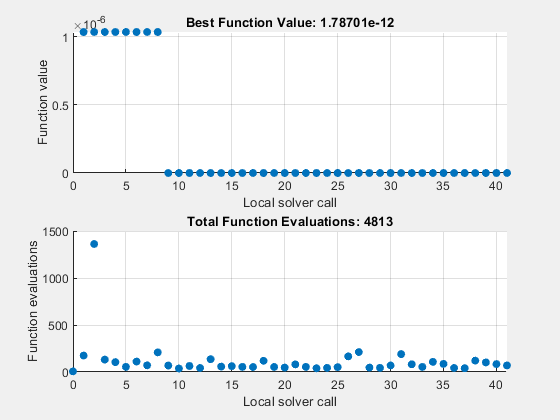

sol = struct with fields:
       L: 13.2119
       Q: 2.9430e+03
    Tamb: 26.5274
     Uin: 0.0431
      hc: 1.4187
      wc: 1.1407


fval = 1.7870e-12

exitflag =     LocalMinimumFoundAllConverged


output = struct with fields:
                funcCount: 4917
         localSolverTotal: 41
       localSolverSuccess: 41
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'GlobalSearch stopped because it analyzed all the trial points.↵↵All 41 local solver runs converged with a positive local solver exit flag.'
                    local: [1×1 struct]
      objectiveDerivative: "finite-differences"
     constraintDerivative: "finite-differences"
             globalSolver: 'GlobalSearch'
                   solver: 'fmincon'


optiProblem.Constraints.pressure_lower = 0 <= pressure_drop;
optiProblem.Constraints.temp_lower = 55 <= temperature;
optiProblem.Constraints.temp_upper = temperature <= 60;

% Set up patternsearch options
gs = GlobalSearch("Display","iter", "PlotFcn",{"gsplotbestf", ;"gsplotfunccount"}, ...
                    "FunctionTolerance",0);
opts = optimoptions('fmincon', 'ConstraintTolerance',0);

% Set initial guess
[x0.hc, x0.wc, x0.L, x0.Tamb, x0.Q, x0.Uin] = deal(1.5, 1, 60, 28.3, 3156, 10);

% Solve the optimization problem
[sol, fval, exitflag, output] = solve(optiProblem, x0, gs, 'Options', opts)


% Display results
sol

sol = struct with fields:
       L: 13.2119
       Q: 2.9430e+03
    Tamb: 26.5274
     Uin: 0.0431
      hc: 1.4187
      wc: 1.1407


fval

fval = 1.7870e-12

exitflag

exitflag =     LocalMinimumFoundAllConverged


output

output = struct with fields:
                funcCount: 4917
         localSolverTotal: 41
       localSolverSuccess: 41
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'GlobalSearch stopped because it analyzed all the trial points.↵↵All 41 local solver runs converged with a positive local solver exit flag.'
                    local: [1×1 struct]
      objectiveDerivative: "finite-differences"
     constraintDerivative: "finite-differences"
             globalSolver: 'GlobalSearch'
                   solver: 'fmincon'


opt_ip = [sol.hc; sol.wc; sol.L; sol.Tamb; sol.Q; sol.Uin];
pressure_drop = pressure_shallow_net(opt_ip)

pressure_drop = 1.7870e-12

temperature = temp_shallow_net(opt_ip)

temperature = 56.3019

function pressure_drop = objFcn(hc, wc, L, Tamb, Q, Uin, press_net)
    x_val = [hc; wc; L; Tamb; Q; Uin];
    pressure_drop = press_net(x_val);
end

function temperature = constraintFcn(hc, wc, L, Tamb, Q, Uin, temp_net)
    x_val = [hc; wc; L; Tamb; Q; Uin];
    temperature = temp_net(x_val);
end